Load the data.

loaddata % given script

dout = '../Out/' % folder for produced data

../Data/ACTOBS_S01_20161109_1108.mat
../Data/ACTOBS_S02_20161207-1002.mat
../Data/ACTOBS_S03_20161122-1529.mat
../Data/ACTOBS_S04_20161125-1211.mat
../Data/ACTOBS_S05_20161118_1339.mat
../Data/ACTOBS_S06_20161125-1033.mat
../Data/ACTOBS_S07_20161202-1521.mat
../Data/ACTOBS_S08_20161207-1434.mat
../Data/ACTOBS_S09_20161209-0958.mat
../Data/ACTOBS_S10_20161215-1615.mat
../Data/ACTOBS_S11_20161216-1131.mat
../Data/ACTOBS_S12_20161222-1036.mat
../Data/ACTOBS_S13_20161222-1406.mat
../Data/ACTOBS_S14_20170106-1517.mat
../Data/ACTOBS_S15_20170203-1237.mat


    flipped responses for block 1!


../Data/ACTOBS_S16_20170110-1509.mat
../Data/ACTOBS_S17_20170117-1048.mat
../Data/ACTOBS_S18_20170127-1459.mat
../Data/ACTOBS_S20_20170202-1235.mat
../Data/ACTOBS_S21_20170208-1404.mat
../Data/ACTOBS_S22_20170209-1228.mat
../Data/ACTOBS_S23_20170210-0956.mat
../Data/ACTOBS_S24_20170215-1430.mat
../Data/ACTOBS_S25_20170216-1146.mat
../Data/ACTOBS_S26_20170306-1121.mat
../Data/ACTOBS_S27_20170228-1126.mat
../Data/ACTOBS_S28_20170222-1442.mat
../Data/ACTOBS_S29_20170224-1500.mat
../Data/ACTOBS_S30_20170227-1227.mat
../Data/ACTOBS_S31_20170303-1217.mat
../Data/ACTOBS_S32_20170310-1222.mat
../Data/ACTOBS_S33_20170323-1400.mat
../Data/ACTOBS_S34_20170324-1142.mat
../Data/ACTOBS_S35_20170327-1331.mat
../Data/ACTOBS_S36_20170331-1156.mat
../Data/ACTOBS_S37_20170405-1006.mat
../Data/ACTOBS_S38_20170428-1701.mat


    flipped responses for block 3!


../Data/ACTOBS_S39_20170407-1250.mat
../Data/ACTOBS_S40_20170413-1019.mat
../Data/ACTOBS_S41_20170414-1217.mat
../Data/ACTOBS_S42_20170512-1659.mat
../Data/ACTOBS_S43_20170420-1010.mat


    flipped responses for block 3!


../Data/ACTOBS_S44_20170421-1000.mat
../Data/ACTOBS_S45_20170426-1613.mat
../Data/ACTOBS_S46_20170428-1010.mat
../Data/ACTOBS_S47_20170503-1206.mat
../Data/ACTOBS_S48_20170505-1619.mat
../Data/ACTOBS_S49_20170505-1459.mat


    flipped responses for block 4!


../Data/ACTOBS_S50_20170512-1014.mat
../Data/ACTOBS_S51_20170519-1218.mat
../Data/ACTOBS_S52_20170523-0945.mat
../Data/ACTOBS_S53_20170526-1234.mat
../Data/ACTOBS_S54_20170602-0957.mat
../Data/ACTOBS_S55_20170607-1243.mat
../Data/ACTOBS_S56_20170609-1512.mat
../Data/ACTOBS_S57_20170623-0958.mat
../Data/ACTOBS_S58_20170623-1507.mat
../Data/ACTOBS_S59_20170630-1425.mat
../Data/ACTOBS_S60_20170630-1230.mat
../Data/ACTOBS_S61_20170710-1045.mat
../Data/ACTOBS_S62_20170711-1605.mat
../Data/ACTOBS_S63_20170713-1206.mat
../Data/ACTOBS_S64_20170721-1024.mat
../Data/ACTOBS_S65_20170725-1611.mat
../Data/ACTOBS_S66_20170731-1328.mat
../Data/ACTOBS_S67_20170904-1326.mat
../Data/ACTOBS_S68_20170929-1722.mat
../Data/ACTOBS_S69_20170911-1111.mat
../Data/ACTOBS_S70_20170914-1002.mat
../Data/ACTOBS_S71_20170918-1305.mat
../Data/ACTOBS_S72_20170919-1123.mat
../Data/ACTOBS_S73_20170925-1300.mat
../Data/ACTOBS_S74_20170927-1335.mat
../Data/ACTOBS_S75_20171002-1207.mat
../Data/ACTOBS_S76_20171003-1445.mat
.

Inital fits ('nrep' number of fits) of the actual data to obtain an estimate of the two variables of interest, the probability of reversal (prev) and the choice variability (beta), that will serve fixed refence values to the next analyses.

nrep = 1e1;

clear prev_fit beta_fit
[prev_fit, beta_fit] = initialfit(nrep, nsubj, dat, subjlist);

dout = '../Out/'

mean_prev_fit = 0.2087

mean_beta_fit = 1.2439

Using a (given) function "sim_model_softmax", dataset are simulated using the fixed parameters (nsim simulated datasets).

nsim              = 30;                % number of simulations
nttest            = 100;               % number of ttests
ndiff             = [0      0   ; ...
                     0.01   0   ; ...
                     0.02   0   ; ...
                     0.03   0   ; ...
                     0.04   0   ; ...
                     0.05   0   ; ...
                     0.1    0   ; ...
                     0      0.1 ; ...
                     0      0.2 ; ...
                     0      0.3 ; ...
                     0      0.4 ; ...
                     0      0.5 ; ...
                     0      1   ]     % couples of difference to be tested

ndiff =          0         0
    0.0100         0
    0.0500         0
    0.1000         0
         0    0.1000
         0    0.5000
         0    1.0000


nsubjsubset       = [24]           % number of participants (w/out consideration for medical condition, 96 = all)

nsubjsubset = 24


prev_diffsigni_acrossdiff = zeros(1, 2, length(nsubjsubset), 1); % significant ttest counter across the differences tested
beta_diffsigni_acrossdiff = zeros(1, 2, length(nsubjsubset), 1);

revindexdiff = 0

revindexdiff = 0

for idiff = ndiff'
    revindexdiff = revindexdiff+1; % to facilitate counting of the difference outside the loop
    idiff
    prev_fix = [mean_prev_fit-(idiff(1)/2) mean_prev_fit+(idiff(1)/2)]
    beta_fix = [mean_beta_fit-(idiff(2)/2) mean_beta_fit+(idiff(2)/2)]
    
    prev_ttest = zeros(nttest, 5, length(nsubjsubset)); % ttest results saved
    beta_ttest = zeros(nttest, 5, length(nsubjsubset));
    
    prev_diffsigni = zeros(1, 2, length(nsubjsubset)); % significant ttest counter
    beta_diffsigni = zeros(1, 2, length(nsubjsubset));
    
    for isubjsubset = nsubjsubset
            prev_recov = zeros(isubjsubset,2,nsim);
            beta_recov = zeros(isubjsubset,2,nsim);
            
            isubjsubset
            seq_isubjsubsest = randperm(nsubj,isubjsubset)
        for ittest = 1:nttest
            for isubj = seq_isubjsubsest
                for itask = 1:2
                    
                    % filter trials of interest
                    ifilt = dat.subj == subjlist(isubj) & dat.task == itask;
                    
                    % simulate model
                    cfg_sim        = [];
                    cfg_sim.nsim   = nsim;
                    cfg_sim.seqllr = dat.evid(ifilt);
                    cfg_sim.seqind = dat.sind(ifilt);
                    cfg_sim.prev   = prev_fix(itask);
                    cfg_sim.beta   = beta_fix(itask);
                    cfg_sim.brep   = 0; % force no repetition bias
                    cfg_sim.epsi   = 0; % force no lapses
                    
                    out_sim        = sim_model_softmax(cfg_sim);
                

        Then each datasets is fit using the (given) function "fit_model_softmax".

                    % fit simulated decisions
                    for isim = 1:nsim
                        cfg_fit        = [];
                        cfg_fit.seqllr = out_sim.cfg.seqllr;
                        cfg_fit.seqind = out_sim.cfg.seqind;
                        cfg_fit.raft   = out_sim.raft(:,isim);
                        cfg_fit.rbef   = out_sim.rbef(:,isim);
                        cfg_fit.brep   = out_sim.cfg.brep; % force no repetition bias
                        cfg_fit.epsi   = out_sim.cfg.epsi; % force no lapses
                            
                        out_recov = fit_model_softmax(cfg_fit);
                        

        Estimated value of prev and beta from each simulation are stored and their average value is computed.

                        % store model parameters
                        revindexsubj = find(seq_isubjsubsest==isubj);
                        % isubj goes over the index limit --> reverse indexing with 
                        % find(seq_isubjsubsest == isubj)
                        prev_recov(revindexsubj,itask,isim) = out_recov.prev;
                        beta_recov(revindexsubj,itask,isim) = out_recov.beta;
                    end    
                end
            end

        Paired-sample t-test for each prev_recov(task1)-prev_recov(task2)       %or for or each beta_recov(task1)-beta_recov(task2)  

            revindexsubset = find(nsubjsubset==isubjsubset);    
            
            [h,p,ci,stats] = ttest(prev_recov(1,1,:),prev_recov(1,2,:));
            prev_ttest(ittest, 1, revindexsubset) = h;
            prev_ttest(ittest, 2, revindexsubset) = p;
            prev_ttest(ittest, 3, revindexsubset) = ci(:,:,1);
            prev_ttest(ittest, 4, revindexsubset) = ci(:,:,2);
            prev_ttest(ittest, 5, revindexsubset) = stats.sd;
            
            [h,p,ci,stats] = ttest(beta_recov(1,1,:),beta_recov(1,2,:));
            beta_ttest(ittest, 1, revindexsubset) = h;
            beta_ttest(ittest, 2, revindexsubset) = p;
            beta_ttest(ittest, 3, revindexsubset) = ci(:,:,1);
            beta_ttest(ittest, 4, revindexsubset) = ci(:,:,2);
            beta_ttest(ittest, 5, revindexsubset) = stats.sd;
            
        end
        
        prev_diffsigni(:,:,revindexsubset) = [length(find(prev_ttest(:,1,revindexsubset) == 1)) nttest];
        beta_diffsigni(:,:,revindexsubset) = [length(find(beta_ttest(:,1,revindexsubset) == 1)) nttest];
        
        
    end
    
%     revindexdiff = find(idiff == ndiff)
    prev_diffsigni_acrossdiff(:,:,:,revindexdiff) = prev_diffsigni
    beta_diffsigni_acrossdiff(:,:,:,revindexdiff) = beta_diffsigni
    
    str_nsubjsubset = '';
    for isubjsubset = nsubjsubset
        str_nsubjsubset = [str_nsubjsubset, num2str(isubjsubset),'-'];
    end
    str_nsubjsubset = str_nsubjsubset(1:end-1) % to delete the last (useless) '-'
    
    formatSpec_file = '%s%s_(%g-%g)diff_%ssubj_%dx%dsim.mat';
    
    name_prev_ttest = sprintf(formatSpec_file, dout,'prev_ttest',idiff(1),idiff(2),str_nsubjsubset,nttest,nsim);
    save(name_prev_ttest, 'idiff','nsubjsubset','nsim','nttest','prev_ttest','prev_diffsigni')
    
    name_beta_ttest = sprintf(formatSpec_file, dout,'beta_ttest',idiff(1),idiff(2),str_nsubjsubset,nttest,nsim);
    save(name_beta_ttest, 'idiff','nsubjsubset','nsim','nttest','beta_ttest','beta_diffsigni')
    %['../Out/prev_ttest_(',num2str(idiff(1)),'-',num2str(idiff(2)),')diff_',str_nsubjsubset,'subj_',num2str(nttest),'x',num2str(nsim),'sim.mat']
    
end

revindexdiff = 1

idiff =      0
     0


prev_fix =     0.2087    0.2087


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     88    95    11    51    15    53    25    80    68    32    37    20     8    78    22    63    33    81     9    27    28    26    30    36


prev_diffsigni_acrossdiff =      5   100


beta_diffsigni_acrossdiff =      4   100


str_nsubjsubset = '24'

revindexdiff = 2

idiff =     0.0100
         0


prev_fix =     0.2037    0.2137


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     53    65    20    10     7    68    19     4    90    34    83    96    18    12    11    75    94    67    85    27    84    37     3    57


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     5   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     8   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


str_nsubjsubset = '24'

revindexdiff = 3

idiff =     0.0500
         0


prev_fix =     0.1837    0.2337


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     76    45    48    82    41    95    51    61    31    18    86    22    90    11    43    79    81     2    29    78    34     6    56    19


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     5   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    96   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     5   100


str_nsubjsubset = '24'

revindexdiff = 4

idiff =     0.1000
         0


prev_fix =     0.1587    0.2587


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     96     1    12    79    34    26    17    94    29    14     9    69    73    18    77    25    86    74    76    80    78     6    27    85


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     5   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    96   100


prev_diffsigni_acrossdiff(:,:,1,4) =

   100   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


str_nsubjsubset = '24'

revindexdiff = 5

idiff =          0
    0.1000


prev_fix =     0.2087    0.2087


beta_fix =     1.1939    1.2939


isubjsubset = 24

seq_isubjsubsest =     90    27    61    85    10    39    23    81    47     5    82    57    52    84    59    77    96    24    20    86    29    75    34    51


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     5   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    96   100


prev_diffsigni_acrossdiff(:,:,1,4) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,5) =

     1   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    30   100


str_nsubjsubset = '24'

revindexdiff = 6

idiff =          0
    0.5000


prev_fix =     0.2087    0.2087


beta_fix =     0.9939    1.4939


isubjsubset = 24

seq_isubjsubsest =     10    70    34    89    28    59    65    57    32    68    29     1     5    88    50    80    76    36    72    40    35    66    53    13


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     5   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    96   100


prev_diffsigni_acrossdiff(:,:,1,4) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,5) =

     1   100


prev_diffsigni_acrossdiff(:,:,1,6) =

     4   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    30   100


beta_diffsigni_acrossdiff(:,:,1,6) =

   100   100


str_nsubjsubset = '24'

revindexdiff = 7

idiff =      0
     1


prev_fix =     0.2087    0.2087


beta_fix =     0.7439    1.7439


isubjsubset = 24

seq_isubjsubsest =     55    45    26    75    82    52     6    84     2    80    61    41    86    67    51     4    89    28    78    92    46    12    54    23


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     5   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     8   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    96   100


prev_diffsigni_acrossdiff(:,:,1,4) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,5) =

     1   100


prev_diffsigni_acrossdiff(:,:,1,6) =

     4   100


prev_diffsigni_acrossdiff(:,:,1,7) =

     3   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

    30   100


beta_diffsigni_acrossdiff(:,:,1,6) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,7) =

   100   100


str_nsubjsubset = '24'

Plot of significant t-tests as a function of the difference in value for each parameter (only works if the value of the other is kept constant)

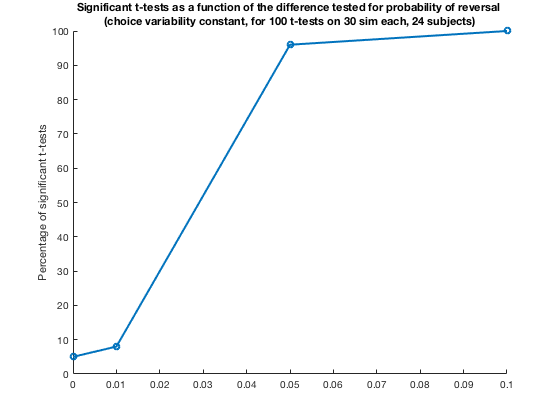

formatSpec_title = ['Significant t-tests as a function of the difference tested for %s ', 10, ...
                    '(%s constant, for %d t-tests on %d sim each, %d subjects)'];
formatSpec_fig = '%s%s_diffsigni_acrossdiff_%dsubj_%dx%dsim';
                


prevonly_diff_index = [1 2 3 4 5]; % to enter manually according to the chosen ndiff
prevonly_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,:,prevonly_diff_index);

y = zeros(length(prevonly_diff_index), 1);
for revindexsubset = 1:length(nsubjsubset)
    for i = 1:length(prevonly_diff_index)
        div = prevonly_diffsigni_acrossdiff(:,:,revindexsubset,i);
        y(i) = 100 * div(:,1) ./ div(:,2);
    end
    x = ndiff(prevonly_diff_index,1);
    
    h = figure;
    hold on
    name_title = sprintf(formatSpec_title, 'probability of reversal','choice variability',nttest,nsim,nsubjsubset(revindexsubset));
    title(name_title);
    plot(x,y,'o-','LineWidth',2)
    ylabel('Percentage of significant t-tests');
    hold off
    
    name_fig_prev_diffsigni_acrossdiff = sprintf(formatSpec_fig, dout,'prev',nsubjsubset(revindexsubset),nttest,nsim,'.png');
    saveas(h, name_fig_prev_diffsigni_acrossdiff);   
end

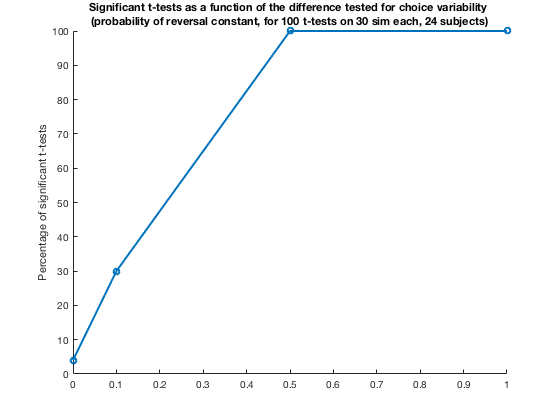




betaonly_diff_index = [1 6 7 8 9]; % to enter manually in function of chosen ndiff
betaonly_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,:,betaonly_diff_index);

y = zeros(length(betaonly_diff_index), 1);
for revindexsubset = 1:length(nsubjsubset)
    for i = 1:length(betaonly_diff_index)
        div = betaonly_diffsigni_acrossdiff(:,:,revindexsubset,i);
        y(i) = 100 * div(:,1) ./ div(:,2);
    end
    x = ndiff(betaonly_diff_index,2);

    h = figure;
    hold on
    name_title = sprintf(formatSpec_title, 'choice variability','probability of reversal',nttest,nsim,nsubjsubset(revindexsubset));
    title(name_title);
    plot(x,y,'o-','LineWidth',2)
    ylabel('Percentage of significant t-tests');
    hold off
    
    name_fig_prev_diffsigni_acrossdiff = sprintf(formatSpec_fig, dout,'beta',nsubjsubset(revindexsubset),nttest,nsim,'.png');
    saveas(h, name_fig_prev_diffsigni_acrossdiff);
end